# CaliAli demo pipeline (parameter selection)

## **Step 0: Load CaliAli parameters**

Modify `CaliAli_demo_parameters` to analyze your own data

CaliAli_options = CaliAli_demo_parameters();

## Step 1: Downsampling

CaliAli_options = CaliAli_downsample_batch(CaliAli_options);

Now reading /Users/johnmarshall/Documents/Analysis/miniscope_analysis/caliAliData/T_maze/08142025/denoised1_gray.tif
File /Users/johnmarshall/Documents/Analysis/miniscope_analysis/caliAliData/T_maze/08142025/denoised1_gray_ds.mat already exist in destination folder!


## Step 2: Motion Correction

#### Blood vessels size estimation (for motion correction):

First, we need to estimate the optimal blood vessel (BV) size for motion correction.

*Note: The BV size estimated at this stage may be noisy, as it is based on a single frame of the video. A more accurate estimation will be required after motion correction.*

BVsize=BV_app();

The chosen Blood vessels sizes are [0.10, 0.70]


% Update CaliAli_options with new BV size.
CaliAli_options = CaliAli_parameters(CaliAli_options,'BVsize',BVsize);

Now we perform motion correction:

CaliAli_options = CaliAli_motion_correction(CaliAli_options);

Automatically set batch size to 3500 frames based on 16.0 GB RAM and (300x300 ) frame size.
Pre-allocating output file: /Users/johnmarshall/Documents/Analysis/miniscope_analysis/caliAliData/T_maze/08142025/denoised1_gray_ds_mc.mat
Pre-allocated file with dimensions [300, 300, 1000]
Processing batch from /Users/johnmarshall/Documents/Analysis/miniscope_analysis/caliAliData/T_maze/08142025/denoised1_gray_ds.mat
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 9 workers.

ans = 

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 9
                 Busy: false
              Cluster: 

Always check that the video is correctly motion corrected!

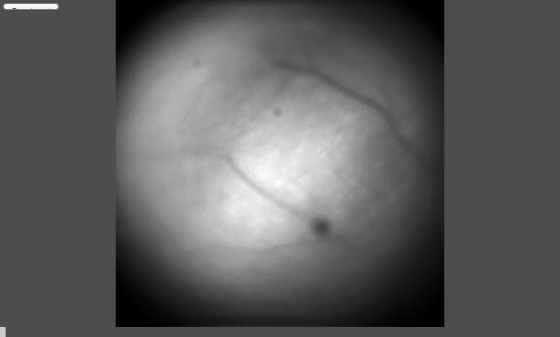

view_Ca_video();

## **Pre-alignment Step: Estimating Optimal Parameters**

#### Blood vessels size estimation (for inter-session alignment):

Now we will estimate the optimal BV size. To do this, run the BV detection app again using the motion-corrected video. The BVs should appear much clearer at this stage, as CaliAli uses the median frame for BV estimation.

BVsize=BV_app(); %Choose a file with the *_mc* tag. 

The chosen Blood vessels sizes are [0.10, 1.25]


% Update CaliAli_options with new BV size.
CaliAli_options = CaliAli_parameters(CaliAli_options,'BVsize',BVsize);

#### Neuron size estimation:

Now we will estimate the optimal neuron size:

gSig=NeuronSize_app(1:0.5:12); %Choose a file with the *_mc* tag. 

The chosen Neuron size is [2.00]


% Update CaliAli_options with new gSig size.
CaliAli_options = CaliAli_parameters(CaliAli_options,'gSig',gSig);

## Step 3: Align Sessions

CaliAli_options = CaliAli_align_sessions(CaliAli_options);

Automatically set batch size to 800 frames based on 16.0 GB RAM and (599x600 ) frame size.
Pre-allocating output file: /Users/johnmarshall/Documents/Analysis/miniscope_analysis/caliAliData/m7_day1_2_9_test/parameterSelectionTest/Day2rec_2025_01_21_11_02_23_My_V4_Miniscope_24_ds_mc_det.mat
Pre-allocated file with dimensions [599, 600, 1000]
Pre-allocating output file: /Users/johnmarshall/Documents/Analysis/miniscope_analysis/caliAliData/m7_day1_2_9_test/parameterSelectionTest/Day2rec_2025_01_21_11_02_23_My_V4_Miniscope_25_ds_mc_det.mat
Pre-allocated file with dimensions [599, 600, 1000]
Pre-allocating output file: /Users/johnmarshall/Documents/Analysis/miniscope_analysis/caliAliData/m7_day1_2_9_test/parameterSelectionTest/Day2rec_2025_01_21_11_02_23_My_V4_Miniscope_44_ds_mc_det.mat
Pre-allocated file with dimensions [600, 600, 1000]
Pre-allocating output file: /Users/johnmarshall/Documents/Analysis/miniscope_analysis/caliAliData/m7_day1_2_9_test/parameterSelectionTest/Day2rec_2025_01_21

 🔹 **Note:** If analyzing only one session, run the following instead:

% CaliAli_options = detrend_batch_and_calculate_projections(CaliAli_options);

## Step 4: Evaluating Alignment Performance

Get BV-score:

fprintf('BV Score: %.4f\n', CaliAli_options.inter_session_alignment.BV_score);

BV Score: 12.2117


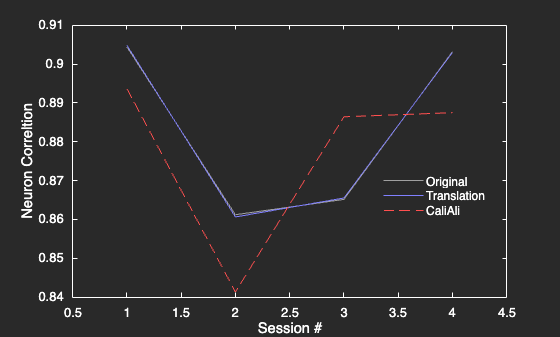

The amplitude of non-rigid misalignment is 7.0% of the average neuron size (12.0px).
Non-rigid misalignment accounts for 0.0% of the total.



% Get alignment metrics (Mean Correlation Score & Crispness - Higher is better)
Alignment_metrics = CaliAli_options.inter_session_alignment.alignment_metrics;
plot_alignment_scores(CaliAli_options);

drawnow;

## Step 5: Create Video of Aligned Projections

Extract and visualize the aligned projections

Processing:  000%  |            | 0/4it [00:00:00<Inf:NaN:NaN, Inf it/s]


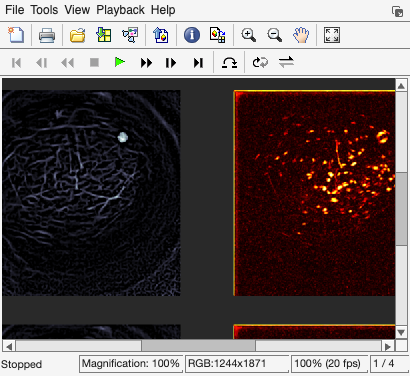

P = CaliAli_options.inter_session_alignment.P;
frame = plot_P(P); % Create a video of the projections

## Step 6: Run CNMF-E

🔹 ***Optionional (Recommended)***: Estimate CNMFe initialization parameters using the CaliAli App 

CaliAli_set_initialization_parameters(CaliAli_options);

🔹 Extract neurons:

File_path = CaliAli_cnmfe(); % Select "250207_191126_ses03_mc_ds_Aligned.mat"

## Step 7: Optional Post-Processing 

Load the neuron data

% load(File_path{end});


 🔹 Manually label components using the post-processing app

% ix = postprocessing_app(neuron, 0.6);


 🔹 Review or delete labeled components

% neuron.viewNeurons(find(ix), neuron.C_raw);  % View labeled components
% neuron.delete(ix);  % Delete unwanted components


 🔹 Manually merge neurons with less conservative parameters

% neuron.merge_high_corr(1, [0.3, 0.2, -inf]);


 🔹 Save the neuron data

% save_workspace(neuron);

## Step 8: Update Residuals

% neuron = manually_update_residuals(neuron,0.6, 1);

## 🔹 Useful Commands

Visualize temporal traces

% view_traces(neuron);

 Save results in a new path (choose a new 'source_extraction' folder)

neuron = update_folder_path(neuron);
cnmfe_path = neuron.save_workspace();
